addpath 'Live Scripts'\ 'Data'\ 'Utility Functions'\;
set(groot,'defaultAxesTickLabelInterpreter','latex'); 
set(groot,'defaulttextinterpreter','latex');
set(groot,'defaultLegendInterpreter','latex');

Here, I'm plotting the collection of velocities of the stratified panel first as a two-dimensional set of translational velocities. 

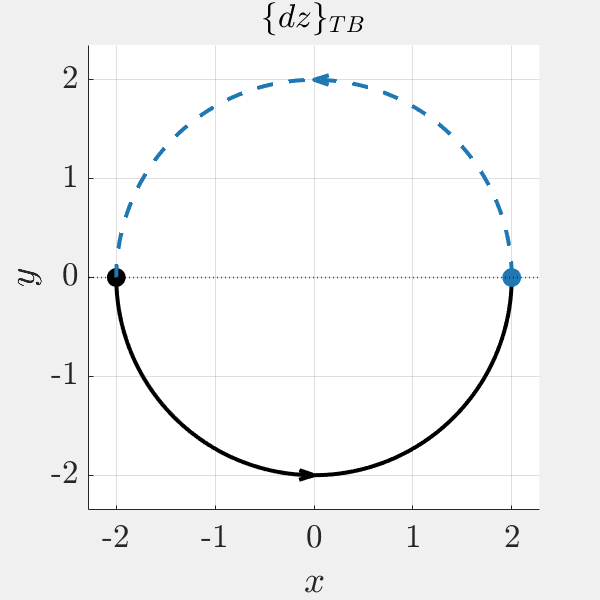

dnum = 101; a = linspace(-pi/2, pi/2, dnum);
mul = 2;
dz12x = mul*sin(a); dz12y = -mul*cos(a);
dz12xN = -dz12x; dz12yN = -dz12y;

% dot_title_txt_x = '$$\{dz^{x}\}_{T B}$$'; 
% dot_title_txt_y = '$$\{dz^{y}\}_{T B}$$'; 
dot_title_txt_x = '$$x$$'; 
dot_title_txt_y = '$$y$$'; 

negCol = [31, 120, 180]/255;

fS = 25;

domainPercentage = 5; arrowAngle = deg2rad(18);
arrowSize = domainPercentage/100*pi;

f = figure('units', 'pixels', 'position', [0 0 600 600]); set(f,'Visible','on');
ax = gca; hold(ax, "on"); grid(ax, "on"); 
plot(ax, dz12x,  dz12y,  'k-', 'LineWidth', 3.0);
plotPathArrowV2(ax, dz12x, dz12y,...
                arrowSize, arrowAngle, 3.0, 'k', 'mid');
scatter(ax, dz12x(1), dz12y(1), 200, "k", "filled", "o");
plot(ax, dz12xN, dz12yN, '--', 'LineWidth', 3.0, "Color", negCol);
plotPathArrowV2(ax, dz12xN, dz12yN,...
                arrowSize, arrowAngle, 3.0, negCol, 'mid');
scatter(ax, dz12xN(1), dz12yN(1), 200, negCol, "filled", "o");
xline(ax, 0, 'k:', LineWidth=1.2);
yline(ax, 0, 'k:', LineWidth=1.2);
axis(ax, "equal", "padded"); ax.FontSize = fS;
xlabel(ax, dot_title_txt_x); ylabel(ax, dot_title_txt_y); axis(ax, "square", "equal", "padded");
title(ax, '$$\{dz\}_{T B}$$', 'Interpreter', 'latex', "FontSize", fS);

Then we shall obtain a plot for the displacement of such a system and plot it componentwise as heatmaps. The axes in this plot are the starting and ending points of the trajectory.

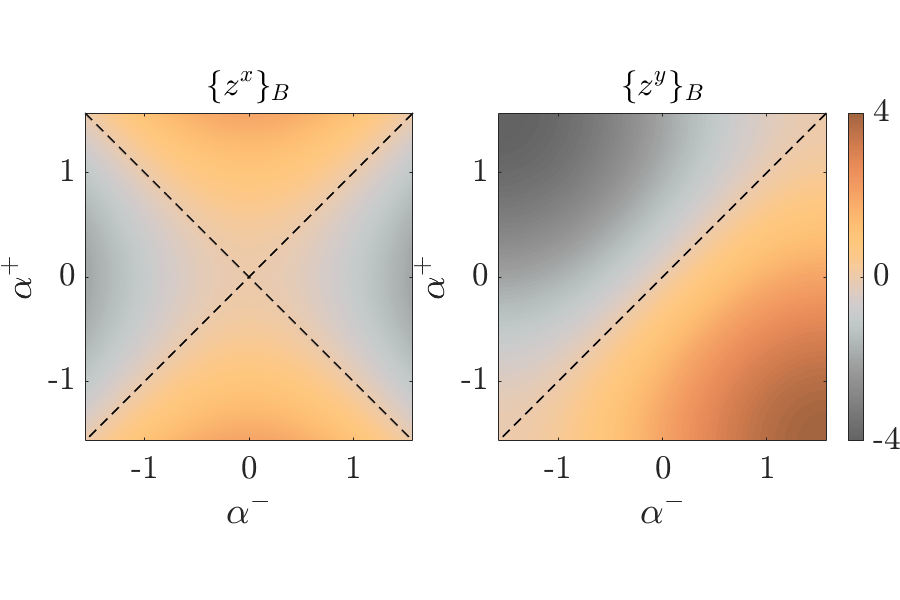

am = a; ap = a;
[aM, aP] = meshgrid(am, ap);
amlimits = [ -pi/2, pi/2 ]; aplimits = amlimits;
mul = -2;
z12x = mul*(cos(aP) - cos(aM)); z12y = mul*(sin(aP) - sin(aM));
zLimits = [min([z12x(:); z12y(:)], [], "all"), ...
           max([z12x(:); z12y(:)], [], "all")];
cfLvl = dnum; 
lW_contour = 0.4;
CUB = flipud([159.3750,99.6030,63.4312;
          239.0625,149.4045,95.1469;
          255.0000,199.2060,126.8625;
            204,204,204;
            150,150,150;
            99,99,99])/255; % define CUB colormap and interpolate for more colors
CUB = interpColorAndCondition((1:size(CUB, 1))', CUB, ... % X, V
    (linspace(1, size(CUB, 1), size(turbo, 1)))'); % Xq
del_title_txt_x = '$$\{z^{x}\}_{B}$$'; 
del_title_txt_y = '$$\{z^{y}\}_{B}$$'; 
xTxt = '$$\alpha^{-}$$';
yTxt = '$$\alpha^{+}$$';

% obtain the zero contours
xZeroContoursRaw = contourc(am, ap, z12x, [0, 0]);
[~, xZeroContours] = contourArrToCells(xZeroContoursRaw);
yZeroContoursRaw = contourc(am, ap, z12y, [0, 0]);
[~, yZeroContours] = contourArrToCells(yZeroContoursRaw);


f = figure('units', 'pixels', 'position', [0 0 900 600], ...
    'Color','w'); set(f,'Visible','on');
tl = tiledlayout(f, 1, 2, "tilespacing", "tight", "padding", "tight");

ax = nexttile(tl);
contourf(ax, aM, aP, z12x, cfLvl, 'LineStyle', 'none');
axis equal tight; hold on; 
for i = 1:numel(xZeroContours)
    plot(ax, xZeroContours{i}(1, :), xZeroContours{i}(2, :), 'k--', 'LineWidth', 1.2);
end
xlabel(ax, xTxt, "FontSize", fS);
ylabel(ax, yTxt, "FontSize", fS);
title(ax, del_title_txt_x, 'Color', 'k', "FontSize", fS, "Interpreter", "latex");
ax.XAxis.FontSize = fS; ax.YAxis.FontSize = fS; 
xlim(amlimits); ylim(aplimits); colormap(ax, CUB); clim(ax, zLimits);

ax = nexttile(tl);
contourf(ax, aM, aP, z12y, cfLvl, 'LineStyle', 'none');
axis equal tight; hold on; 
for i = 1:numel(yZeroContours)
    plot(ax, yZeroContours{i}(1, :), yZeroContours{i}(2, :), 'k--', 'LineWidth', 1.2);
end
xlabel(ax, xTxt, "FontSize", fS);
ylabel(ax, yTxt, "FontSize", fS);
title(ax, del_title_txt_y, 'Color', 'k', "FontSize", fS, "Interpreter", "latex");
ax.XAxis.FontSize = fS; ax.YAxis.FontSize = fS; 
xlim(amlimits); ylim(aplimits); colormap(ax, CUB); clim(ax, zLimits);

cb = colorbar('FontSize', fS, ...
              'TickLabelInterpreter', 'latex', ...
              'Ticks', linspace(zLimits(1), zLimits(2), 3));
cb.Layout.Tile = "east";

Finally,  we plot the bounds of the gait reachable sets for the two-foot system in the displacement space. This is similar to the plots made in "se2_toyproblems_case_1_mobility.mlx".

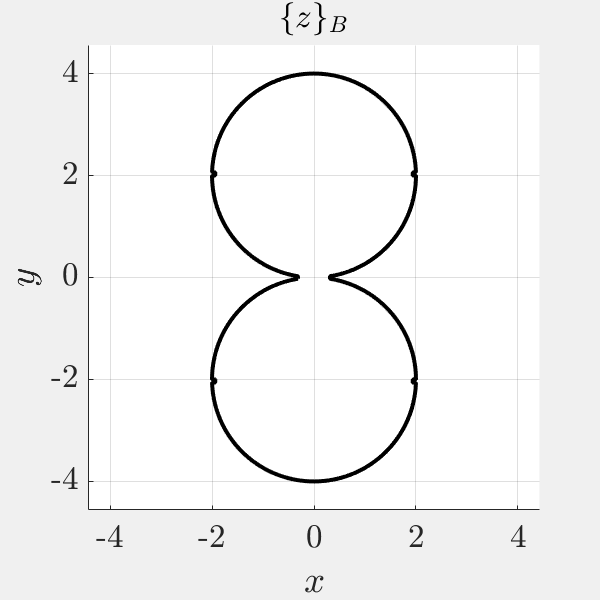

boundIdx = boundary(z12x(:), z12y(:), 1);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
f = figure('units', 'pixels', 'position', [0 0 600 600]); set(f,'Visible','on');
ax = gca; hold(ax, "on"); grid(ax, "on"); 
% scatter(ax, z12x, z12y)
plot(ax, z12x(boundIdx), z12y(boundIdx), 'k-', 'LineWidth', 3.0);
axis(ax, "equal", "padded"); ax.FontSize = fS;
xlabel(ax, "$$x$$"); ylabel(ax, '$$y$$'); axis(ax, "square", "equal", "padded");
title(ax, '$$\{z\}_{B}$$', 'Interpreter', 'latex', "FontSize", fS);